This tutorial will guide you on loading, manipulating, and visualizing the training data and labels.

We will begin by getting the file names for the training data in the dataset/train folder and return a sorted list for the file paths.

% Searching for training data within the dataset folder
filepath = {};
files = dir('../dataset/train/*.csv');
for i=1:length(files)
    filepath = [filepath; fullfile('../dataset/train/', files(i).name)];
end

% path to labels
labeldir = '../dataset/labels.csv'

labeldir = '../dataset/labels.csv'


disp(filepath)

    {'../dataset/train/001.csv'}
    {'../dataset/train/002.csv'}
    {'../dataset/train/003.csv'}
    {'../dataset/train/004.csv'}
    {'../dataset/train/005.csv'}



Next, we will be loading one of the training data.

% Load the forth training data
idx_data = 4;

data = readtable(filepath{idx_data});


% Print the loaded data
disp(data);

    Eccentricity    SemimajorAxis_km_    Inclination_deg_    RAAN_deg_    ArgumentOfPeriapsis_deg_    TrueAnomaly_deg_    Latitude_deg_    Longitude_deg_    Altitude_km_    J2kX_km_    J2kY_km_    J2kZ_km_    J2kVx_km_s_    J2kVy_km_s_    J2kVz_km_s_
    ____________    _________________    ________________    _________    ________________________    ________________    _____________    ______________    ____________    ________    ________    ________    ___________    ___________    _________

We will then load the label data

% Load label data
node_label_all = readtable(labeldir);

% Extract the label for a single object ID
node_label = node_label_all(node_label_all.ObjectID == idx_data, :);

% Print the label data
disp(node_label);

    ObjectID    TimeIndex    Direction     Node      Type 
    ________    _________    _________    ______    ______

       4             0        {'EW'}      {'SS'}    {'CK'}
       4             0        {'NS'}      {'SS'}    {'NK'}
       4           275        {'EW'}      {'ID'}    {'NK'}
       4           298        {'EW'}      {'AD'}    {'NK'}
       4          1040        {'EW'}      {'IK'}    {'CK'}
       4          2172        {'ES'}      {'ES'}    {'ES'}



We will then visualize the data and label the data with the node labels.

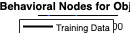

% Create a figure
fig = figure('Position', [100, 100, 1200, 300]);

% Get the gist_rainbow colormap
cm = parula(height(node_label));

% Plot the training data
plot(data.Longitude_deg_, 'k', 'LineWidth', 2, 'DisplayName', 'Training Data');
hold on;

% Plot vertical lines for each node label
for ik = 1:height(node_label)-3
    if strcmp(node_label.Direction{ik+2}, 'EW')
        linestyle = '-';
    else
        linestyle = '--';
    end
    
    % Plot vertical line
    xline(node_label.TimeIndex(ik+2), ...
        'Color', cm(ik,:), 'LineStyle', linestyle, 'LineWidth', 2, ...
        'DisplayName', "EW-"+node_label.Node{ik+2}+"-"+node_label.Type{ik+2});
end

% Set plot properties
title(['Behavioral Nodes for Object ' num2str(idx_data)]);
xlabel('Time');
ylabel('Longitude (deg)');
legend();
grid on;
hold off;

Meanwhile for the NS nodes.

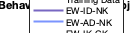

% Create a figure
fig = figure('Position', [100, 100, 1200, 300]);

% Get the gist_rainbow colormap
cm = parula(height(node_label));

% Plot the training data
plot(data.Inclination_deg_, 'k', 'LineWidth', 2, 'DisplayName', 'Training Data');
hold on;

% Plot vertical lines for each node label
for ik = 1:height(node_label)-3
    if strcmp(node_label.Direction{ik+2}, 'EW')
        linestyle = '-';
    else
        linestyle = '--';
    end
    
    % Plot vertical line
    xline(node_label.TimeIndex(ik+2), ...
        'Color', cm(ik,:), 'LineStyle', linestyle, 'LineWidth', 2, ...
        'DisplayName', "EW-"+node_label.Node{ik+2}+"-"+node_label.Type{ik+2});
end

% Set plot properties
title(['Behavioral Nodes for Object ' num2str(idx_data)]);
xlabel('Time');
ylabel('Inclination (deg)');
legend('Location', 'Best');
grid on;
hold off;